# ME 535 Assignment 7 - Fall 2018

# Debabrata Auddya

**Exercise 6.2(e) :**

dsdu = [0.399 -0.399 -1.518];
dsdv = [-1.991 -1.991 0];
disp('The normal vector is given by')

The normal vector is given by


x = cross(dsdu,dsdv)

x =    -3.0223    3.0223   -1.5888


suv = [1.309 -1.309 1.621];
y = dot(suv,x)

y = -10.4880

disp('The equation of the tangent plane is given as')

The equation of the tangent plane is given as


disp('-3.0223x + 3.0223y -1.5888z = -10.4880')

-3.0223x + 3.0223y -1.5888z = -10.4880



$$-3.0223x + 3.0223y -1.5888z = -10.4880$$


**Exercise 6.2 (f) :**

Render this patch and its control net.

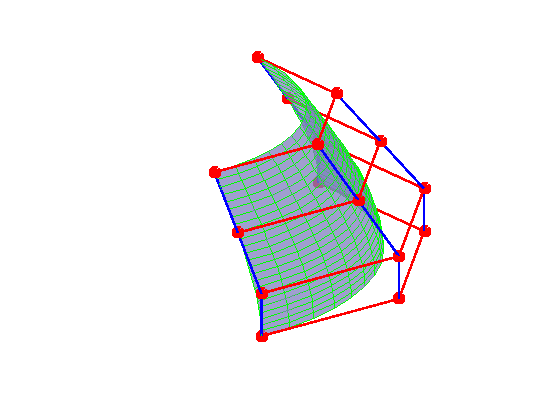

clear all, close all;

% control points A for a degree 3 * 3 patch
 P =  [1.5 0 2.4; 1.5 -0.84 2.4; 0.84 -1.5 2.4; 0 -1.5 2.4;
       1.75 0 1.875; 1.75 -0.98 1.875; 0.98 -1.75 1.875; 0 -1.75 1.875;
       2 0 1.35; 2 -1.12 1.35; 1.12 -2 1.35; 0 -2 1.35;
       2 0 0.9; 2 -1.12 0.9; 1.12 -2 0.9; 0 -2 0.90];  % Example problem
 nr = 4;
 nc = 4;
 
% surface evaluation
u = 1/2.; v = 1/2.;
tQ = deCasteljauSurf(P,nr, nc, u, v);


%number of sampled points
snr = 25; % number of sampled points in row (in u direction)
snc = 15; % number of sampled points in col (in v direction)
hold on;
Q = bezierSurf(P, nr, nc, snr, snc);
%plot the surface
bezierSurfPlot(P, Q, nr, nc, snr, snc);
view(3)

axis off;

**Exercise 6.3**

Render the B´ezier patch and its control net

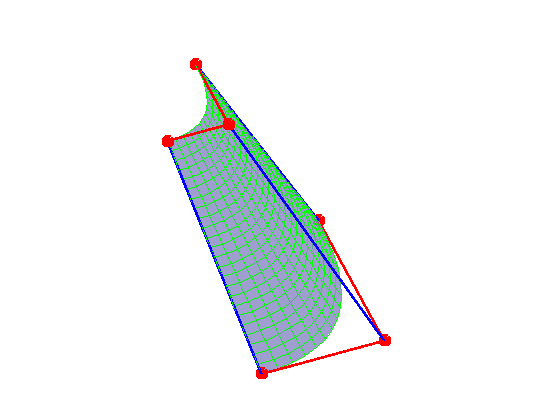

clear all; 
close all;
%close all;
figure(1)
% Control poits for a degree 2 * 1 patch
P1 = [0 -4 0; 1 -4 0; 2 0 0;
    0 -2 2; 0.5 -2 2; 1 0 2;];
 nr = 2;
 nc = 3;
 
% surface evaluation
u = 1/2.; v = 1/2.;
tQ = deCasteljauSurf(P1,nr, nc, u, v);


%number of sampled points
snr = 25; % number of sampled points in row (in u direction)
snc = 15; % number of sampled points in col (in v direction)
%hold on;
Q1 = bezierSurf(P1, nr, nc, snr, snc);
%plot the surface
bezierSurfPlot(P1, Q1, nr, nc, snr, snc);
view(3)

axis off;

**Functions added:**

**deCasteljau**

function [Q] = deCasteljau(P, u)
% computer point with paremeter value u on bezier curve defined by control points P
% P control points, in matrix format: {size of P} * {dimension of P}
% dimension of P is 2 or 3
% u parameter with value [0 1]
% Q point lying on the bezier curve
% input: P: control points P; u:  parameter value 
% output: Q: the Bezier curve point at u
% example: >> 
%       P = [0 0; 1 2; 3 5; 4,4; 5 0];
% call:  Q=deCasteljau(P, 0.5)
% output:Q =
%   2.6875    3.3750

% m: # of control points; m = the degree of the curve +1
[m, n] = size(P);  
% if m <= 2 
%     err('please specify more than 2 control points');
% end

if u < 0 | u > 1
    err('u must be in range from 0 to 1');
end

for i=1:(m-1)
    for j=1:(m-i) % the array index in Matlab starts with 1, not 0.
        P(j,:) = (1-u)*P(j,:) + u*P(j+1,:); 
        % ':' meaning for all the columns: x, y, z
    end
end

Q=P(1,:);
end

**Bezier Surf Plot:**

function bezierSurfPlot(P, Q, nl, nc, snl, snc)
% plot the given control points P and points Q on beizer curve
% P control points
% Q points on bezier curve
% nr number of rows of control points
% nc number of columns of control points
% snl number of sampled points in u-dir
% snc number of sampled points in v-dir

hold on;
%plot control points
for i=0:(nl-1)
     PL = P((i*nc+1):(i+1)*nc,:);
     plot3(PL(:,1),PL(:,2),PL(:,3),'-ro', 'linewidth',2,'MarkerFaceColor', 'r', 'MarkerSize',8);
     hold on;
end

for i=0:(nc-1)
     k = (i+1):nc:(nc*nl);
     PL = P(k,:);
     plot3(PL(:,1),PL(:,2),PL(:,3),'-b', 'linewidth',2);
end

%plot surface points
% for i=0:(snl-1)
%      QL = Q((i*snc+1):(i+1)*snc,:);
%      plot3(QL(:,1),QL(:,2),QL(:,3),'-g');
%      hold on;
% end
% 
% for i=0:(snc-1)
%      k = (i+1):snc:(snc*snl);
%      QL = Q(k,:);
%      plot3(QL(:,1),QL(:,2),QL(:,3),'-g');
% end

%figure(2);

[r,c] = size(Q);
out   = (reshape(Q,[snc,snl, c]));
 p = surf(out(:,:,1),out(:,:,2), out(:,:,3));
 
% style 1 
%  p.EdgeColor=0.1*[1 1 1 ];
%  p.FaceAlpha=.75;
%  p.FaceColor='green';

 % style 2
p.FaceColor = [0.5 0.5 0.75];
p.FaceAlpha=.75; %0.75 %.75;
p.EdgeColor = 'green'; %'interp';
p.LineStyle = '-'; %'none';'



hold off;
end

**deCasteljau surf function**

function [Q] = deCasteljauSurf(P, nr, nc, u, v)
%P bezier control points with format [p0; p1; p2;....p(nr*nc)]
%every p(i) is of form (x, y, z) or (x, y)
%nr number of rows
%nc number of columns
%u  u-parameter value
%v  v-parameter value

for i=0:(nr-1)  %do decasteljau on every row in v-dir
    PR = P((i*nc+1):(i+1)*nc,:);  % i-th row CPs
    QR(i+1,:) = deCasteljau(PR, v);
end
Q = deCasteljau(QR, u);  %do decastlejau in u-dir
end

**Bezier surf function**

function [Q] = bezierSurf(P, nr, nc, snr, snc)
% return points on the surface.
% compute points on bezier surface defined by control points P
% P control points, in matrix format: {size(nr*nc) of P} * {dimension of P}
% nr number of rows of control points
% nc number of colums of control points
% snr the number of points need to be computed in row
% snc the number of points need to be computed in column
% Q points lying on the bezier surface

i = 1;
for u=0:(1/(snr-1)):1
    for v=0:(1/(snc-1)):1
    Q(i,:) = deCasteljauSurf(P,nr, nc, u, v);
    i = i + 1;
    end
end
end 